path = [pwd '\BloodSmearImages\babesiosis'];
ims = imageDatastore(path);

Properties for class matlab.io.datastore.ImageDatastore:

    Files
    Folders
    AlternateFileSystemRoots
    ReadSize
    Labels
    SupportedOutputFormats
    DefaultOutputFormat
    ReadFcn



Methods for class matlab.io.datastore.ImageDatastore:

ImageDatastore   countEachLabel   isPartitionable  partition        readall          shuffle          transform        
combine          delete           isShuffleable    preview          readimage        splitEachLabel   writeall         
copy             hasdata          numpartitions    read             reset            subset           

Methods of matlab.io.datastore.ImageDatastore inherited from handle.



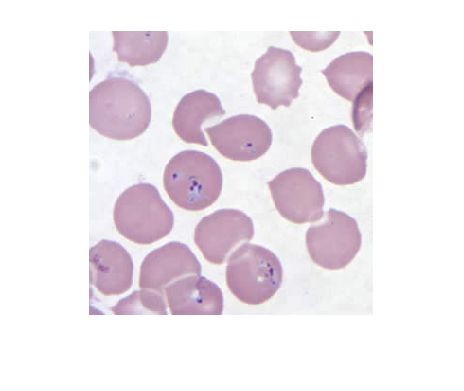

properties(ims)

Image = readimage(ims,4);

mask = createMask(Image);

imshowpair(Image,mask,'montage')

[mask2, props] = filterRegions(mask);

Unrecognized function or variable 'filterCellRegions'.

imshowpair(mask,mask2,'montage')

edit refinedMask.m

[centers,radii] = segmentCellCircles(Image);

clf; imshow(Image)
viscircles(centers,radii,'edgecolor','b');
title(sprintf('%i Cells Detected',numel(radii)),'fontsize',14);

tmp = readimage(ims,16);

clf;
imshowpair(Image,tmp,'montage')
title('Varying Image Quality')

% Read the documentation for IMHISTMATCH and use IMHISTMATCH to correct tmpImg with targetImage
match = imhistmatch(tmp,Image);

clf;
imshowpair(Image,match,'montage')
title('Histogram Matched Images')

edit refinedMask_final

function [BW_out,properties] = filterRegions(BW_in)
%filterRegions  Filter BW image using auto-generated code from imageRegionAnalyzer app.
%  [BW_OUT,PROPERTIES] = filterRegions(BW_IN) filters binary image BW_IN
%  using auto-generated code from the imageRegionAnalyzer app. BW_OUT has
%  had all of the options and filtering selections that were specified in
%  imageRegionAnalyzer applied to it. The PROPERTIES structure contains the
%  attributes of BW_out that were visible in the app.

% Auto-generated by imageRegionAnalyzer app on 23-Sep-2022
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out, 'Area', [200, 6206]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});

% Uncomment the following line to return the properties in a table.
% properties = struct2table(properties);
end

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 23-Sep-2022
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 1.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.024;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.936;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end




